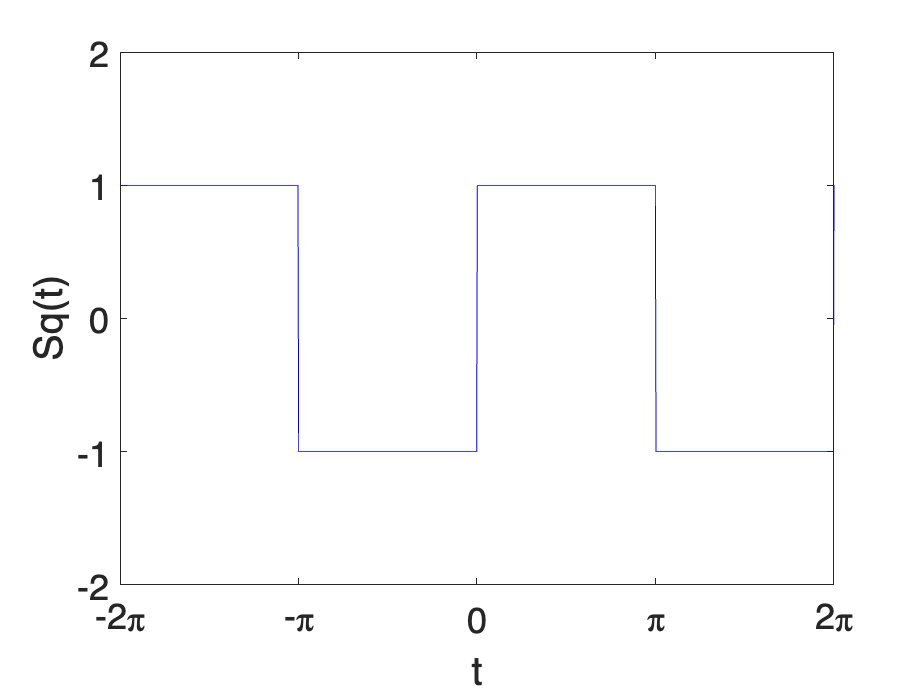

%Create a vector t of 1000 evenly spaced values between -2*pi and 2*pi.
t = linspace(-2*pi, 2*pi, 1000);
% Create a vector Sq that is equal to the square wave on inputs given by the vector t.
Sq = square(t);

%Plot the square wave with t on the horizontal axis.
plot(t,Sq,'blue')

%The following set the spacing of ticks and labels on the x and y axes
%It sets the labels and increases the fontsize for readability
xticks([-2*pi -pi 0 pi 2*pi])
xticklabels({'-2\pi','-\pi','0','\pi','2\pi'})
yticks([-2 -1 0 1 2])
ylim([-2 2])
xlabel('t'); ylabel('Sq(t)')
set(gca,'fontsize',18)

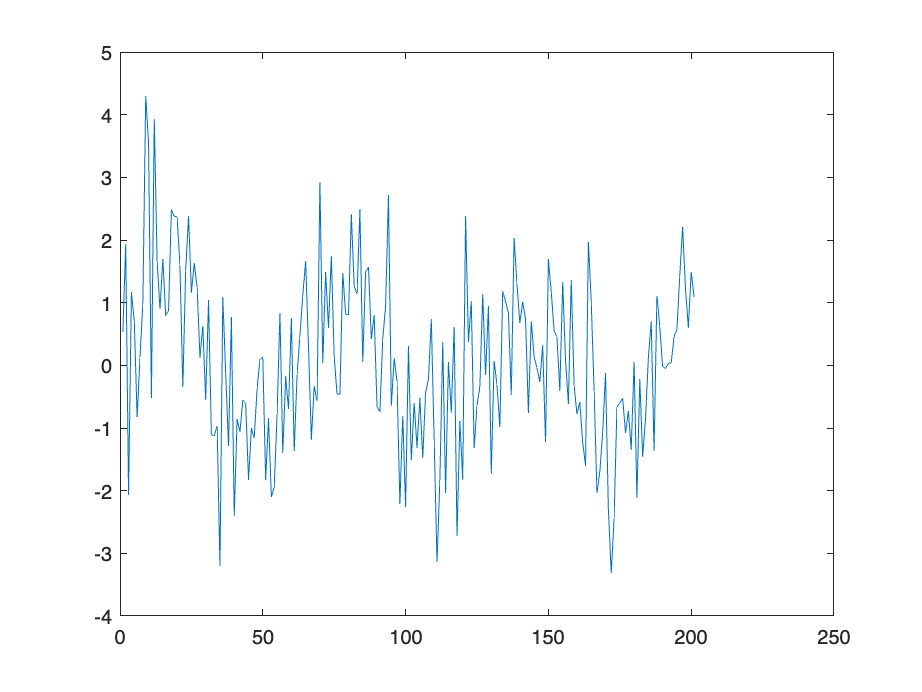

% Create time vector
t = 0: 0.1: 20;

% Compute magnitude vector
y = sin(t);

% Compute the noise vector, noiseY
noiseY = randn(1,201);

% Compute the resulting noisy signal, resSignal
resSignal = noiseY+y;
plot(resSignal);

%Create the function(s) you will need to compute the following coefficients.

p = @(t) t.*sin(61*t);
q = @(t) abs(t).*cos(77*t);

%Find the coefficient b61 of the sawtooth wave.
%(Don't forget the correct constant multiple.)
b61 = (2/pi)*integral(p,0,pi)

b61 = 0.0328


%Find the coefficient a77 of the triangle wave.
%(Don't forget the correct constant multiple.)
a77 = (2/pi)*integral(q,0,pi)

a77 = -2.1475e-04

% Initialize the vector evenNumbers to be all zeros
evenNumbers=zeros(1,10);
% Use a for loop to save the kth *even* number between 2 and 20 
% to the kth entry of the vector evenNumbers
for k = 1:10
   evenNumbers(k) = k*2; 
end
evenNumbers

evenNumbers =      2     4     6     8    10    12    14    16    18    20


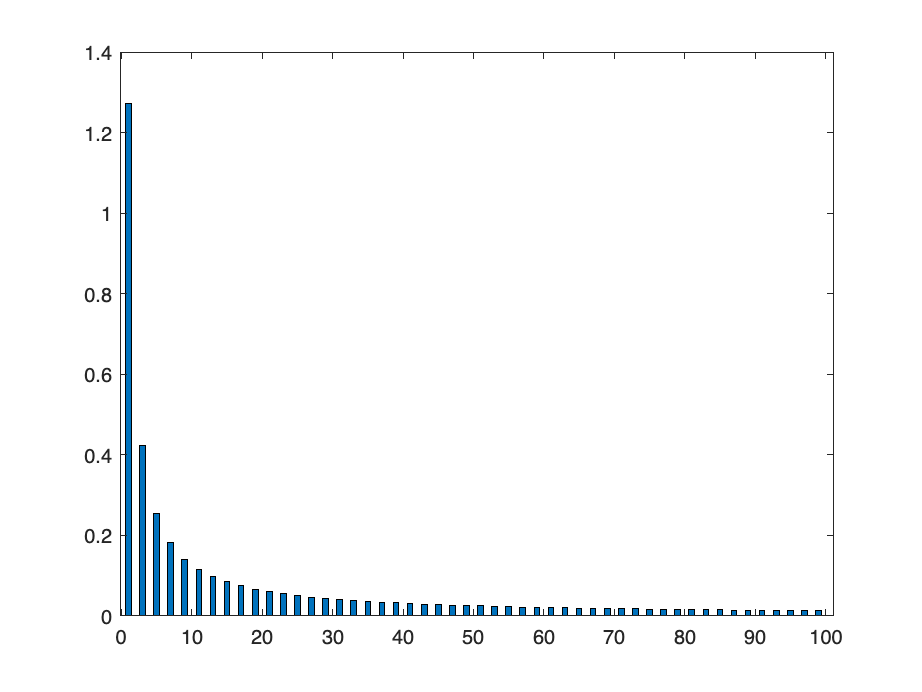

% Create a vector of zeros to store our coefficients
b = zeros(1,100);

%Determine the range of values you much let k range over
for k= 1:100
    %For each index k define a function to integrate
    f = @(t) sin(k*t);
    %Set the kth entry of b equal to the value of the Fourier coefficient
    b(k) = (2/pi)*integral(f,0,pi);
    % If b(k) is small, set to 0 since we want to discount nonzero numbers due to numerical error 
    if b(k)<10^-5
        b(k) = 0;
    end
end

%Display bar graph of coefficients
bar(b);

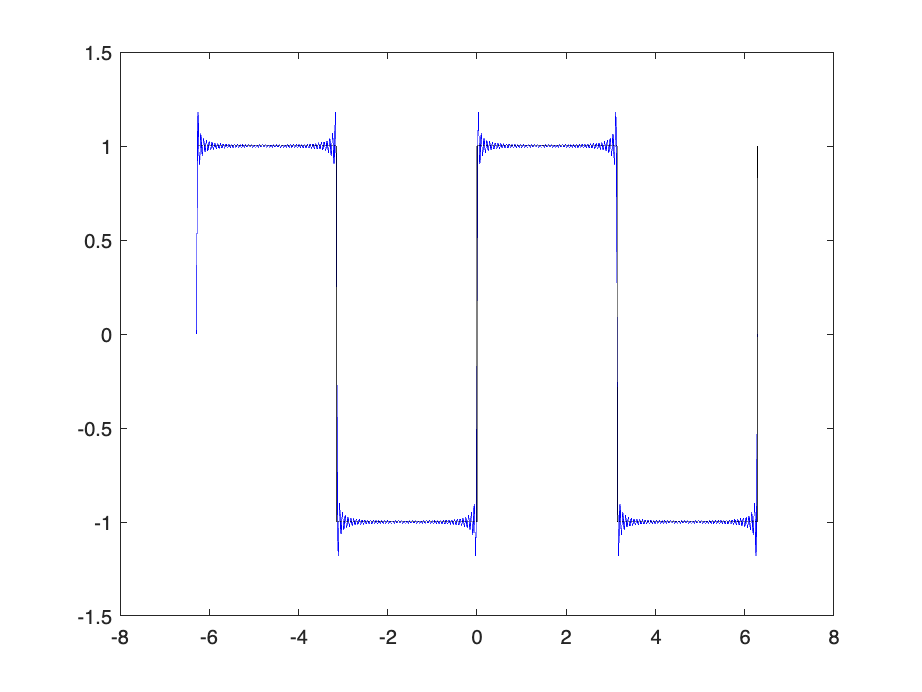

b = zeros(1,100);
t = linspace(-2*pi,2*pi,10^5);
N = length(t);
Sq = square(t);


%% COPY and PASTE the for loop you found from the problem above.
for k= 1:100
    %For each index k define a function to integrate
    f = @(t) sin(k*t);
    %Set the kth entry of b equal to the value of the Fourier coefficient
    b(k) = (2/pi)*integral(f,0,pi);
    % If b(k) is small, set to 0 since we want to discount nonzero numbers due to numerical error 
    if b(k)<10^-5
        b(k) = 0;
    end
end


%Compute superposition of truncated Fourier series
FSterms = zeros(100,N);

%First, multiply each coefficient by the appropriate sin function
for j=1:100
    if b(j) > 10^-5
        % Give an expression for the jth Fourier term
        FSterms(j,:) = b(j)*sin(j*t);
    end
end

%Take the sum of the first 100 terms
SqFS = sum(FSterms);

%Plot the Sq and the SqFS
plot(t,SqFS,'b'); hold on;
plot(t,Sq,'k');

%Create a vector t of 1000 evenly spaced values between -2*pi and 2*pi.
t = linspace(-2*pi, 2*pi, 1000);
% Create a vector Sq that is equal to the square wave on inputs given by the vector t.
Sq = square(t);

%Plot the square wave with t on the horizontal axis.
plot(t,Sq,'blue')

%The following set the spacing of ticks and labels on the x and y axes
%It sets the labels and increases the fontsize for readability
xticks([-2*pi -pi 0 pi 2*pi])
xticklabels({'-2\pi','-\pi','0','\pi','2\pi'})
yticks([-2 -1 0 1 2])
ylim([-2 2])
xlabel('t'); ylabel('Sq(t)')
set(gca,'fontsize',18)

% Create time vector
t = 0: 0.1: 20;

% Compute magnitude vector
y = sin(t);

% Compute the noise vector, noiseY
noiseY = randn(1,201);

% Compute the resulting noisy signal, resSignal
resSignal = noiseY+y;
plot(resSignal);

%Create the function(s) you will need to compute the following coefficients.

p = @(t) t.*sin(61*t);
q = @(t) abs(t).*cos(77*t);

%Find the coefficient b61 of the sawtooth wave.
%(Don't forget the correct constant multiple.)
b61 = (2/pi)*integral(p,0,pi)

%Find the coefficient a77 of the triangle wave.
%(Don't forget the correct constant multiple.)
a77 = (2/pi)*integral(q,0,pi)


% Initialize the vector evenNumbers to be all zeros
evenNumbers=zeros(1,10);
% Use a for loop to save the kth *even* number between 2 and 20 
% to the kth entry of the vector evenNumbers
for k = 1:10
   evenNumbers(k) = k*2; 
end
evenNumbers

% Create a vector of zeros to store our coefficients
b = zeros(1,100);

%Determine the range of values you much let k range over
for k= 1:100
    %For each index k define a function to integrate
    f = @(t) sin(k*t);
    %Set the kth entry of b equal to the value of the Fourier coefficient
    b(k) = (2/pi)*integral(f,0,pi);
    % If b(k) is small, set to 0 since we want to discount nonzero numbers due to numerical error 
    if b(k)<10^-5
        b(k) = 0;
    end
end

%Display bar graph of coefficients
bar(b);

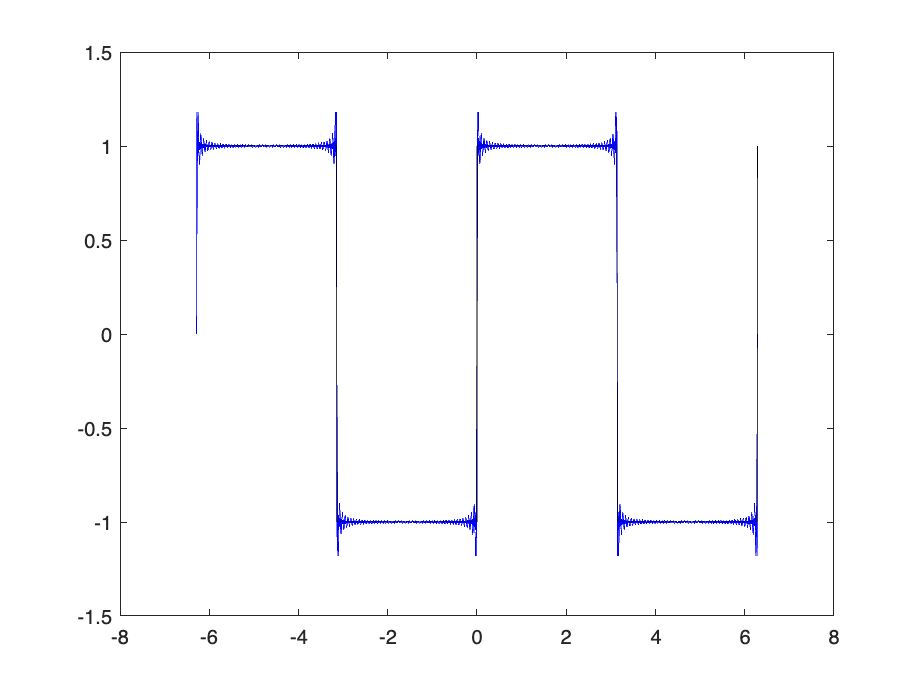

numb = 500;
b = zeros(1,numb);
t = linspace(-2*pi,2*pi,10^5);
N = length(t);
Sq = square(t);


%% COPY and PASTE the for loop you found from the problem above.
for k= 1:numb
    %For each index k define a function to integrate
    f = @(t) sin(k*t);
    %Set the kth entry of b equal to the value of the Fourier coefficient
    b(k) = (2/pi)*integral(f,0,pi);
    % If b(k) is small, set to 0 since we want to discount nonzero numbers due to numerical error 
    if b(k)<10^-5
        b(k) = 0;
    end
end


%Compute superposition of truncated Fourier series
FSterms = zeros(numb,N);

%First, multiply each coefficient by the appropriate sin function
for j=1:numb
    if b(j) > 10^-5
        % Give an expression for the jth Fourier term
        FSterms(j,:) = b(j)*sin(j*t);
    end
end

%Take the sum of the first numb terms
SqFS = sum(FSterms);

%Plot the Sq and the SqFS
plot(t,SqFS,'b'); hold on;
plot(t,Sq,'k');